## Example 2-5. 

#### A  15-kVA, 2300/1230-V transformer is to be tested to determine its excitation branch components, its series impedances, and its voltage regulation. The following test data have been taken from the transformer:

#### The data have been taken by using the connections shown in Figures 2-19 and 2-20. 

#### (a) Find the equivalent circuit of this transformer referred to the high-voltage side. 

#### (b) Find the equivalent circuit of this transformer referred to the low-voltage side.  

#### (c) Calculate the full-load voltage regulation at 0.8 lagging power factor, 1.0 power factor, and at 0.8 leading power factor using the exact equation for Vp. 

#### (d) Plot the voltage regulation as load is increased from no load to full load at power factors of 0.8 lagging, 1.0, and 0.8 leading. 

#### (e) What is the efficiency of the transformer at full load with a power factor of 0.8 lagging? 

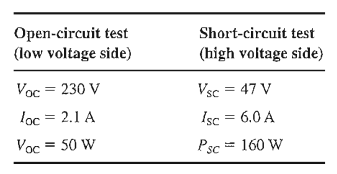

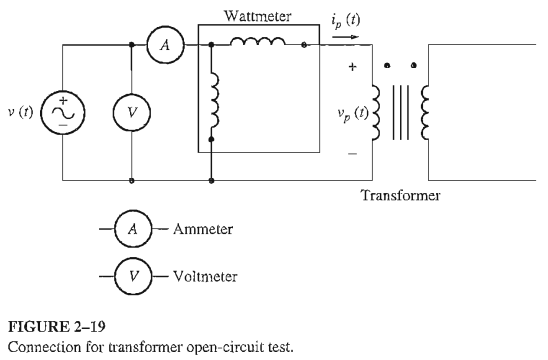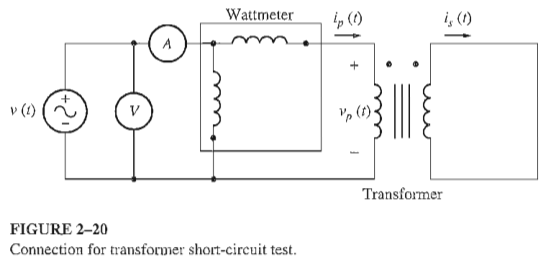

Sreted = 15000;
Vsrated = 230;
Voc = 230;
Ioc = 2.1;
Poc = 50;
Vsc = 47;
Isc = 6.0;
Psc = 160;
a = 10;

#### (a)  ------------------------------------------------------------------------------------

% (a)
% Open-circuit test
thetaoc = acos(Poc / (Voc * Ioc));
disp(['thetaoc = ',num2str(thetaoc * 180/pi)]);

thetaoc = 84.0581


YE = Ioc/Voc;
[Gc, Bm] = pol2cart(thetaoc, YE);
disp(['YE = ', num2str(Gc), ' + j', num2str(Bm)]);

YE = 0.00094518 + j0.0090814


Rc = 1/Gc;
Xm = 1/Bm;
disp(['Zc = ', num2str(Rc), ' + j', num2str(Xm)]);

Zc = 1058 + j110.1154



% Short-cricuit test
thetasc = acos(Psc / (Vsc * Isc));
disp(['thetasc = ',num2str(thetasc * 180/pi)]);

thetasc = 55.4326


ZSE = Vsc/Isc;
[Req, Xeq] = pol2cart(thetasc, ZSE);
disp(['ZSE = ', num2str(Req), ' + j', num2str(Xeq)]);

ZSE = 4.4444 + j6.4504


### (b)  ---------------------------------------------------------------------------

Rc = Rc / a^2;
Xm = Xm / a^2;
Req = Req / a^2;
Xeq = Xeq / a^2;

### (c)  ---------------------------------------------------------------------------

Israted = Sreted / Vsrated;
disp(['Israted = ', num2str(Israted)]);

Israted = 65.2174


PF = 0.8 lagging

Israted = conj(Israted * exp(1j * (acos(0.8))));
disp(['Israted = ', num2str(real(Israted)), ' + j', num2str(imag(Israted))]);

Israted = 52.1739 + j-39.1304


% caluate VP's magnitude and phase
VP = Vsrated + Req * Israted + Xeq * exp(1j * (pi/2)) * Israted;
% exp(j⋅2πθ) = cos(2πθ) + jsin(2πθ) //////// exp(j⋅2π) = 0 + j⋅1 = j
disp(['Vp / a = ', num2str(real(VP)), ' + j', num2str(imag(VP))]);

Vp / a = 234.8429 + j1.6263


[theta, VP] = cart2pol(real(VP), imag(VP));
disp(['VP = ', num2str(VP), ' /_', num2str(theta * 180/pi)]);

VP = 234.8486 /_0.39677


VR = (VP - Vsrated) / Vsrated;
VP2 = abs(VP);
disp(['VR = ', num2str(VR * 100), ' %']);

VR = 2.1081 %


PF = 1.0

Israted = 65.2;
% caluate VP's magnitude and phase
VP = Vsrated + Req * Israted + Xeq * exp(1j * (pi/2)) * Israted;
disp(['Vp / a = ', num2str(real(VP)), ' + j', num2str(imag(VP))]);

Vp / a = 232.8978 + j4.2057


[theta, VP] = cart2pol(real(VP), imag(VP));
disp(['VP = ', num2str(VP), ' /_', num2str(theta * 180/pi)]);

VP = 232.9357 /_1.0345


VR = (VP - Vsrated) / Vsrated;
disp(['VR = ', num2str(VR * 100), ' %']);

VR = 1.2764 %


PF = 0.8 leading

Israted = Israted * exp(1j * (acos(0.8)));
disp(['Israted = ', num2str(real(Israted)), ' + j', num2str(imag(Israted))]);

Israted = 52.16 + j39.12


% caluate VP's magnitude and phase
VP = Vsrated + Req * Israted + Xeq * exp(1j * (pi/2)) * Israted;
disp(['Vp / a = ', num2str(real(VP)), ' + j', num2str(imag(VP))]);

Vp / a = 229.7948 + j5.1032


[theta, VP] = cart2pol(real(VP), imag(VP));
disp(['VP = ', num2str(VP), ' /_', num2str(theta * 180/pi)]);

VP = 229.8515 /_1.2722


VP1 = abs(VP);
VR = (VP - Vsrated) / Vsrated;
disp(['VR = ', num2str(VR * 100), ' %']);

VR = -0.064577 %


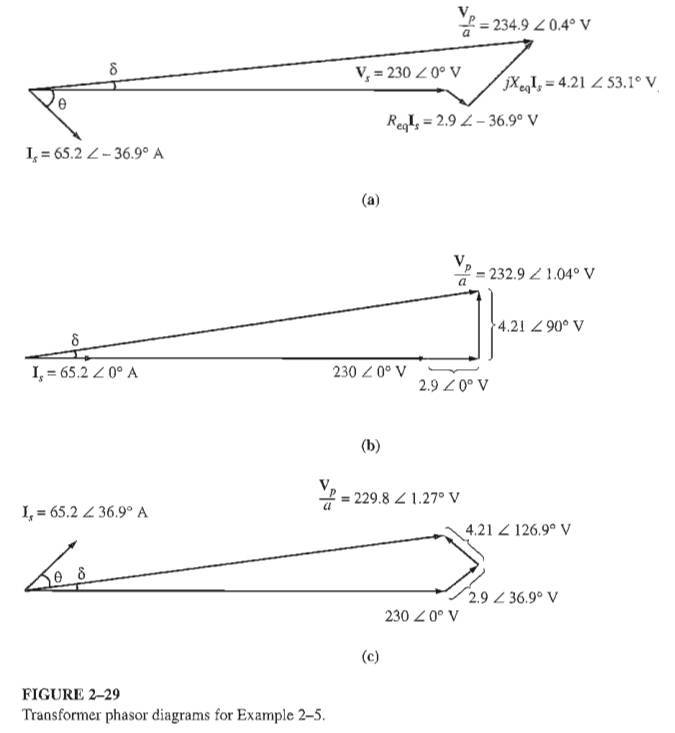

### (d)  ---------------------------------------------------------------------------

amps = 0 : 6.52 : 65.2;
I(1,:) = amps .* (0.8 - 0.6i);  % lagging
I(2,:) = amps .* (1.0);         % unity
I(3,:) = amps .* (0.8 + 0.6i);  % leading

% Calculate VP/a
VPa = Vsrated + Req .* I + 1j .* Xeq .* I;
% Calculate voltage regulation
VR = (abs(VPa) - Vsrated) ./ Vsrated .* 100; 

% Plot the voltage regulation 
plot(amps,VR(1, :),'b-' ) ; 
hold on;
plot(amps, VR(2, :) , 'k--' ) ; 
plot(amps, VR(3 ,:) , 'r-.'); 
title('Voltage Regulation Versus Load'); 
xlabel('Load (A) ') ; 
ylabel('Voltage Regulation (%) '); 
legend('0.8 PF lagging', '1.0 PF', ' 0.8 PF leading') ; 
hold off; 

#### (e)  -------------------------------------------------------------------------------------

% PF = 0.8 lagging
% Issrated = 65.2;

% The copper losses 銅損
Pcu = (abs(Israted))^2 * Req;
disp(['Pcu = ', num2str(Pcu), ' W']);

Pcu = 188.9351 W



% The core losses 鐵芯損
Pcore = (VP2 / a)^2 / Rc;
disp(['Pcore = ', num2str(Pcore), ' W']);

Pcore = 52.1303 W



Pout = real(Vsrated * Israted);
disp(['Pout = ', num2str(Pout), ' W']);

Pout = 11996.8 W



ita = Pout / (Pcu + Pcore + Pout);
disp(['ita = ', num2str(ita * 100), ' %']);

ita = 98.0302 %
